# Smart Cantilever Beam 1D Finite Element Model: Shunt control tuning with Reinforcement Learning

Author: Febvre Maryne

Date: 04/2022 

Objective: This script observes the dynamic behavior of a cantilever beam using a finite element model (FEM). The beam has piezoelectric patches for sensing and actuation. Shunt control is applied on the piezoelectric transducers using, Resistive shunts. Optimal shunt tuning is performed using Deep Reinforcement Learing strategy.

clc 
clf
close all
clear all

Add path to custom functions

addpath("Functions")

Load model data computed from script : 'Smart_cantilever_beam_1D_FEM_livescript.mlx'

load('Datas/FEM_smart_beam.mat','Sys_sc','Sys_oc','Sys_rs')

Flag to save figures (set to 1 to save)

save_figure_var = 0; % 1 to save figure, 0 to not save

Flag to train the algorithm (set true to train)

doTraining = false; %true to train otherwise it load data

Chose the algorithm to train (PPOO or TRPO)

algo = 'TRPO'% 'PPOO' %

algo = 'TRPO'

## Step 1: Define the target

### Shunt control implementation

This section describes how shunt control is implemented in smart structures using the finite element method. An example is given using a resistive (R) shunt. The values chosen here can be used as a reference for achieving automatic tuning or outperforming it.

#### Setup parameters for the feedback control

Define laplace variable:

s = tf('s');

Define system control inputs and outputs

feedin = 1;  % Moment applied (input)
feedout = 1;  % Output is the charge q

Input disturbance of the transfert function 

input_tf = 2; % Input Force Fu, Chose input_tf = 1; for Input q. 

Output measurement of the transfert function 

ouput_tf = 20 ; % Output measurement w_10 displacement at the free beam end. 

#### Resistive Shunt (R)

Electrical Components Definitions

R_value = 1e6 % Define the resistive value in [Ohm]

R_value = 1000000

Define the resistive shunt law

Controle_R_shunt = s * R_value;

Compute the system response with feedback control (resistive shunt)

Sys_rs_crtl_R_shunt = feedback(Sys_rs, Controle_R_shunt, feedin, feedout);

Compute the resistive shunt value using litterature definition from Preumont [1]:

load('Datas/FEM_smart_beam.mat','Kee','d13','E_piezo_13','epsilon_33_S')
% Get the poles and zeros for short circuit case
poles_sc = pole(Sys_sc(ouput_tf, input_tf));
poles_oc = pole(Sys_oc(ouput_tf, input_tf));

% Calculate the natural frequency
omega0_sc_pole = abs(poles_sc(end-1)); % Pole frequency in rad/s
omega0_oc_pole = abs(poles_oc(end-1)); % Pole frequency in rad/s

C = Kee; % Capacitance value (F)
k31 = sqrt(d13^2 / (E_piezo_13 * epsilon_33_S)); % Electromechanical coupling factor
xsi_max_preumont = (omega0_oc_pole - omega0_sc_pole) / (2 * omega0_sc_pole); % Damping factor
gamma_opt = omega0_oc_pole * sqrt(omega0_oc_pole / omega0_sc_pole); % Feedback gain for max damping
R_opt_Preumont = 1 / (gamma_opt * C * (1 - k31^2)); % Optimal resistance for maximum damping
Controle_R_shunt = s * R_opt_Preumont;

Compute the system response with feedback control (resistive shunt)

Sys_rs_crtl_R_shunt_preumont = feedback(Sys_rs, Controle_R_shunt, feedin, feedout);

### Plot figures

#### Bode response

Create a figure for plotting the frequency response results

interval_plot = [2000:0.01:4500];  % Frequency interval for Bode plot

Figure parameters

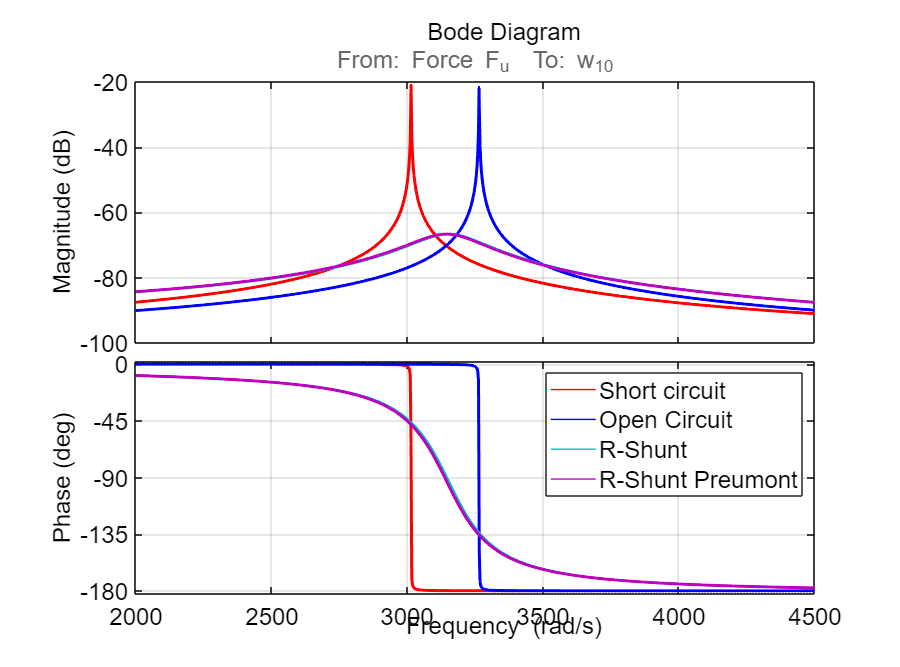

fig1 = figure;
g = bodeoptions;
g.FreqScale = 'Linear';
g.PhaseWrapping = 'on';
g.Grid = 'on';
g.XLim = {[2e3 4.5e3]};  % Frequency limits for the plot
fig1.Name = 'Bode plot';  % Name of the figure


% Plot the frequency responses for Short Circuit and Open Circuit conditions
bodeplot(Sys_sc(ouput_tf, input_tf), 'r', interval_plot,g);  % Short circuit (red)
hold on;
bodeplot(Sys_oc(ouput_tf, input_tf), 'b', interval_plot,g);  % Open circuit (blue)

% Plot the frequency responses for the various shunt conditions
bodeplot(Sys_rs_crtl_R_shunt(ouput_tf, input_tf), interval_plot,g,'c');  % Resistive shunt (cyan)
bodeplot(Sys_rs_crtl_R_shunt_preumont(ouput_tf, input_tf), interval_plot,g,'m');  % Resistive shunt (cyan)
  
legend('Short circuit','Open Circuit','R-Shunt','R-Shunt Preumont');
hold off;

fontsize(fig1, 16, "points")
fig1.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    fig=gcf
    savefig('Figures/Bode_Sys_oc_sc_Rref_shunt')
    save_fig_pdf('Figures/Bode_Sys_oc_sc_Rref_shunt')
end

## Step 2: Reinforcement Learning 

Specify the simulation time `Tf` and the sample time `Ts` in seconds.

Tf = 1;
Ts = 1.0e-5;
time=0:Ts:Tf;

Fix the random generator seed for reproducibility.

rng(0)
noise = rand(length(time),1);

### *Step 2-1: Define Environment:*

Action and observation signals that the agent uses to interact with the environment.

#### *Observation*

- An `rlFiniteSetSpec` object specifies discrete action or observation data specifications for reinforcement learning environments.

- An `rlNumericSpec` object specifies continuous action or observation data specifications for reinforcement learning environments.

numObs = 2;
length([0:Ts:Tf])

ans = 100001


obsInfo=rlNumericSpec([numObs 1], ...
    'LowerLimit',-inf ,...
    'UpperLimit',inf)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [2 1]
       DataType: "double"


obsInfo.Name='observation';
obsInfo.Description='q, w10';

#### *Action*

numAct = 1

numAct = 1

actInfo = rlNumericSpec([numAct 1], ...
    'LowerLimit',[1],...
    'UpperLimit',[7])

actInfo =   rlNumericSpec with properties:

     LowerLimit: 1
     UpperLimit: 7
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


actInfo.Name = 'Contole R';

#### *Environment*

Build the environment interface object.

env=Env_Passive_crtl_freq_time(Sys_rs,Ts,Tf,obsInfo,actInfo,noise,time);

init


### *Step 2-2: Define Agent:*

Define the number of neurones in the hidden layer

nNN=5

nNN = 5

Design the Neural Networks using the custom made functions

criticNet = localCreateCriticNetwork(obsInfo,actInfo,nNN)

criticNet =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     InputNames: {'input_1'}
    OutputNames: {1×0 cell}


Critic = rlValueFunction(criticNet,obsInfo);

actorNet = localCreateActorNetwork(obsInfo,actInfo,nNN)

actorNet =   LayerGraph with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
    Connections: [9×2 table]
     InputNames: {'input_1'}
    OutputNames: {1×0 cell}


Actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
            'ActionMeanOutputNames','scale',...
            'ActionStandardDeviationOutputNames','std',...
            'ObservationInputNames','input_1');

if algo =='TRPO'
    agent = rlTRPOAgent(Actor, Critic)
else 
    agent = rlPPOAgent(Actor, Critic)
end

agent =   rlTRPOAgent with properties:

            AgentOptions: [1×1 rl.option.rlTRPOAgentOptions]
    UseExplorationPolicy: 1
         ObservationInfo: [1×1 rl.util.rlNumericSpec]
              ActionInfo: [1×1 rl.util.rlNumericSpec]
              SampleTime: 1


## Step 3 - Training

### *Step 3-1: Training options:*

**Training Setup**

Configure the training to use the following options:

- Set up the training to last at most 200 episodes, with each episode lasting at most 10 steps.

- To calculate the discounted reward, choose a discount factor of 0.995.

- Terminate the training after the maximum number of episodes is reached or when  the average reward across 10 episodes reaches the value of "stop_training_value".

obs=reset(env)

obs =     0.0001
    0.0416


action = {[log10(R_value)]}; %action = {[log10(R_opt_Preumont)]};
[nextObs,reward,isdone] = step(env,action{1})

Action = 6

distReward = 6.6963

nextObs =     0.0001
    0.0416


reward = 6.6963

isdone = logical
   1


stop_training_value=round(reward,4)

stop_training_value = 6.6963


if algo=='TRPO'
        max_ep=1000;
else 
        max_ep=200;
end

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',max_ep,...
    'MaxStepsPerEpisode',10,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',stop_training_value*1.2,...
    'ScoreAveragingWindowLength',10,...
    'SaveAgentCriteria',"AverageReward", ...
    'SaveAgentValue',400);

### *Step 3-2: Training:*

*GPU parameter*

if canUseGPU
    executionEnvironment = "gpu";
    numberOfGPUs = gpuDeviceCount;
    "can use GPU"
else
    executionEnvironment = "cpu";
    pool = parpool;
end

ans = "can use GPU"

**Custom Training Loop**

The algorithm for the custom training loop is as follows. For each episode:

- Reset the environment.

- Create buffers for storing experience information: observations, actions, and rewards.

- Generate experiences until a terminal condition occurs. To do so, evaluate the  policy to get actions, apply those actions to the environment, and  obtain the resulting observations and rewards. Store the actions,  observations, and rewards in buffers.

- Collect the training data as a batch of experiences.

- Compute the episode Monte Carlo return, which is the discounted future reward.

- Compute the gradient of the loss function with respect to the policy parameters.

- Update the policy using the computed gradients.

- Update the training visualization.

- Terminate training if the policy is sufficiently trained.

if doTraining
    % Train the agent.
    warning('off','all')
    trainingStats = train(agent,env,trainOpts)
else
    % Load the pretrained agent for the example.
    if algo=='TRPO'
        mdl="Datas\Model_EF_Tune_Shunt_R_TRPO.mat";
    else 
        mdl="Datas\Model_EF_Tune_Shunt_R_PPO.mat";
    end
    load(mdl,'agent','trainingStats')
    plot(trainingStats)
end

mdl="Datas\Model_EF_Tune_Shunt_R_TRPO.mat";
load(mdl,'trainingStats')
    
fig2=figure

fig2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


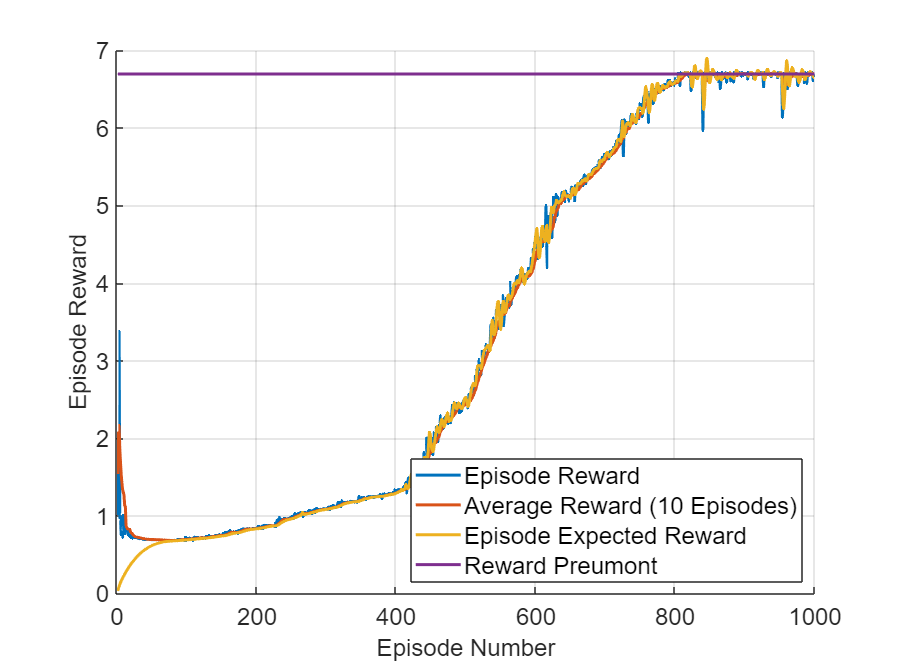

hold on
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeReward)
plot(trainingStats.EpisodeIndex,trainingStats.AverageReward)
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeQ0)
plot([1 trainingStats.EpisodeIndex(end)],[stop_training_value stop_training_value])
    
legend('Episode Reward','Average Reward (10 Episodes)','Episode Expected Reward','Reward Preumont','Location','southeast')
xlabel('Episode Number')
ylabel('Episode Reward')
grid("on")

fontsize(fig2, 16, "points")
fig2.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    savefig('Figures/Training_TRPO_shunt_R')
    save_fig_pdf('Figures/Training_TRPO_shunt_R')
end  

mdl="Datas\Model_EF_Tune_Shunt_R_PPO.mat";
load(mdl,'trainingStats')
    
fig3=figure

fig3 =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


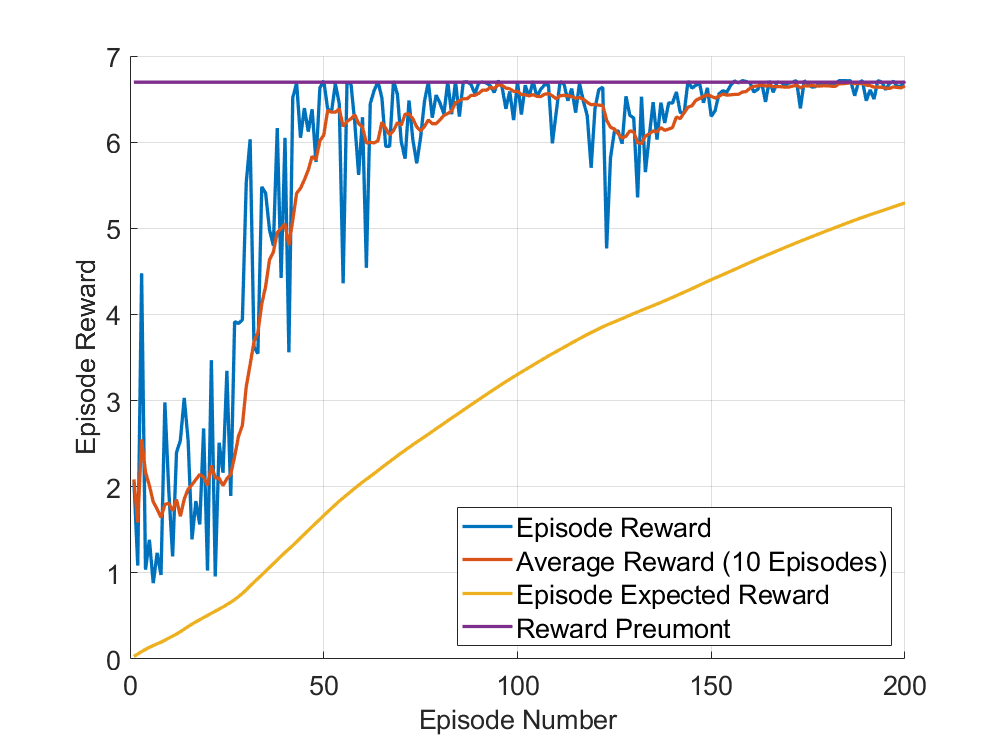

hold on
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeReward)
plot(trainingStats.EpisodeIndex,trainingStats.AverageReward)
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeQ0)
plot([1 trainingStats.EpisodeIndex(end)],[stop_training_value stop_training_value])
    
legend('Episode Reward','Average Reward (10 Episodes)','Episode Expected Reward','Reward Preumont','Location','southeast')
xlabel('Episode Number')
ylabel('Episode Reward')
grid("on")

fontsize(fig3, 16, "points")
fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    savefig('Figures/Training_PPO_shunt_R')
    save_fig_pdf('Figures/Training_PPO_shunt_R')
end

## Step 4 - Plot figures

### Plot training

mdl="Datas\Model_EF_Tune_Shunt_R_TRPO.mat";
load(mdl,'agent')
rng(0)
obs = reset(env);
action = getAction(agent,{obs})

action = 1×1 cell array
    {[5.9206]}


[nextObs,reward,isdone] = step(env,action{1});

Action = 5.9206

distReward = 6.7099

R_opt_TRPO = 10^(action{1})

R_opt_TRPO = 8.3282e+05



mdl="Datas\Model_EF_Tune_Shunt_R_PPO.mat";
load(mdl,'agent')
rng(0)
obs = reset(env);
action = getAction(agent,{obs})

action = 1×1 cell array
    {[6.0864]}


[nextObs,reward,isdone] = step(env,action{1});

Action = 6.0864

distReward = 6.6703

R_opt_PPO = 10^(action{1})

R_opt_PPO = 1.2201e+06

### **Bode Response**

R_shunt=[R_opt_Preumont R_opt_TRPO R_opt_PPO];
color=['r'; 'b'; 'c'; 'k'; 'g'; 'm'];

feedin = 1; %V
feedout = 1; %q

interval_plot=[2000:0.01:4000];
g=bodeoptions;
g.FreqScale='Linear';
g.PhaseWrapping ='on';
g.Grid='on';
g.XLim={[2e3 4e3]};

fig4=figure

fig4 =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


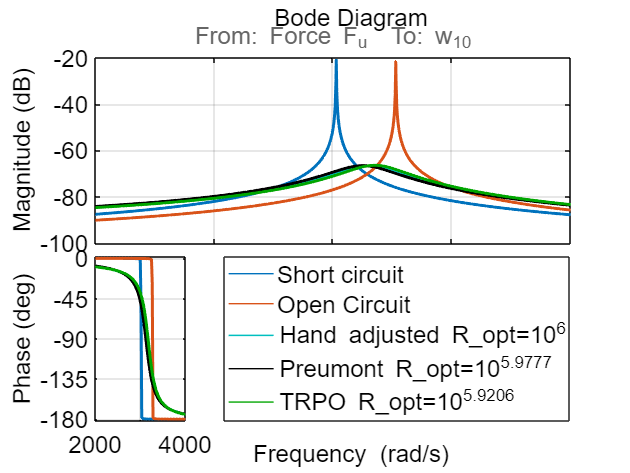

hold on
bode(Sys_sc(end-1,2),interval_plot,g)
bode(Sys_oc(end-1,2),interval_plot,g)

for i=1:length(R_shunt)
    Controle=s*R_shunt(i);
    Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
    bode(Sys_rs_contr_R(end-1,2),interval_plot,color(i+2),g)
end

legend('Short circuit', ...
       'Open Circuit', ...
       'Hand adjusted R_{opt}=10^{'+string(log10(R_value))+'}', ...
       'Preumont R_{opt}=10^{'+string(log10(R_opt_Preumont))+'}', ...
       'TRPO R_{opt}=10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt}=10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','eastoutside')
hold off

fontsize(fig4, 16, "points")
fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    savefig('Figures/Bode_Sys_1D_R_opt_DRL')
    save_fig_pdf('Figures/Bode_Sys_1D_R_opt_DRL')
end

### Pole/Zero Plot

R_shunt=[R_value R_opt_Preumont R_opt_TRPO R_opt_PPO];
color=['r'; 'c'; 'k'; 'g'; 'm'];
marker=['o'; 'x'; 'p'; '+'; 's'; 'd'];

fig5=figure

fig5 =   Figure (14) with properties:

      Number: 14
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


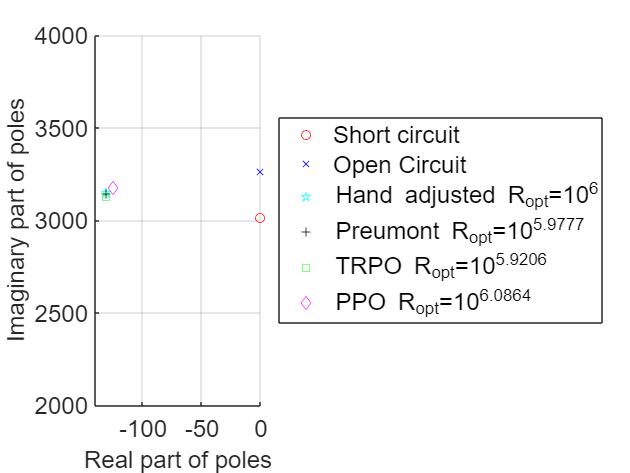

hold on
poles_sc=pole(Sys_sc(end-1,2));
scatter(real(poles_sc),imag(poles_sc),marker(1),color(1))
poles_oc=pole(Sys_oc(end-1,2));
scatter(real(poles_oc),imag(poles_oc),marker(2),color(2))

for i=1:length(R_shunt)
Controle=s*R_shunt(i);
Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
poles_rs=pole(Sys_rs_contr_R);
scatter(real(poles_rs),imag(poles_rs),marker(i+2),color(i+2))
end

xlim([-140 0.01])
ylim([2000 4000])
xlabel('Real part of poles')
ylabel('Imaginary part of poles')

grid("on")
legend('Short circuit', ...
       'Open Circuit', ...
       'Hand adjusted R_{opt}=10^{'+string(log10(R_value))+'}', ...
       'Preumont R_{opt}=10^{'+string(log10(R_opt_Preumont))+'}', ...
       'TRPO R_{opt}=10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt}=10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','eastoutside')

fontsize(fig5, 16, "points")

fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth

if save_figure_var == 1
    savefig('PZ_Sys_1D_R_opt_DRL')
    save_fig_pdf('PZ_Sys_1D_R_opt_DRL')
end

### Noise response

R_shunt=[R_value R_opt_Preumont R_opt_TRPO R_opt_PPO];
color=['r'; 'c'; 'k'; 'g'; 'm'];

fig6=figure

fig6 =   Figure (13) with properties:

      Number: 13
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


plot(env.time,env.w10_0)

for i=1:length(R_shunt)
    reset(env)
    step(env,log10(R_shunt(i)));
    hold on
    plot(env.time(1:length(env.time)/(i)),env.w10(1:length(env.time)/(i)),color(i+2))
end

ans =     0.0001
    0.0416


Action = 6

distReward = 6.6963

ans =     0.0001
    0.0416


Action = 5.9777

distReward = 6.7012

ans =     0.0001
    0.0416


Action = 5.9206

distReward = 6.7099

ans =     0.0001
    0.0416


Action = 6.0864

distReward = 6.6703

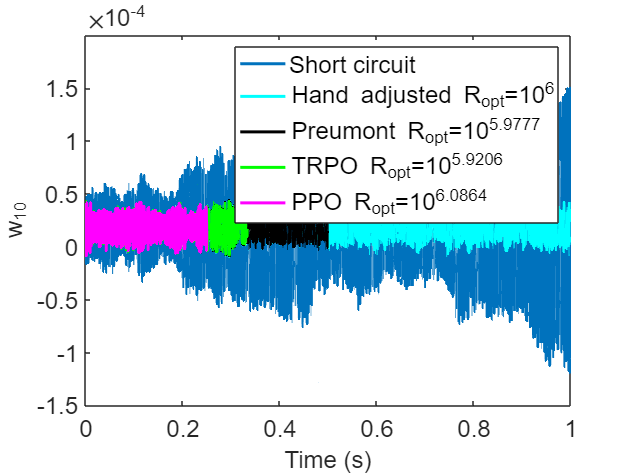


legend('Short circuit', ...
       'Hand adjusted R_{opt}=10^{'+string(log10(R_value))+'}', ...
       'Preumont R_{opt}=10^{'+string(log10(R_opt_Preumont))+'}', ...
       'TRPO R_{opt}=10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt}=10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','northeast')

xlabel('Time (s)')
ylabel('w_{10}')

fontsize(fig6, 16, "points")
fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    savefig('Noise_Sys_1D_R_opt_DRL')
    save_fig_pdf('Noise_Sys_1D_R_opt_DRL')
end

### Impulse response

R_shunt=[R_value R_opt_Preumont R_opt_TRPO R_opt_PPO];
color=['r'; 'c'; 'k'; 'g'; 'm'];

fig7=figure

fig7 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


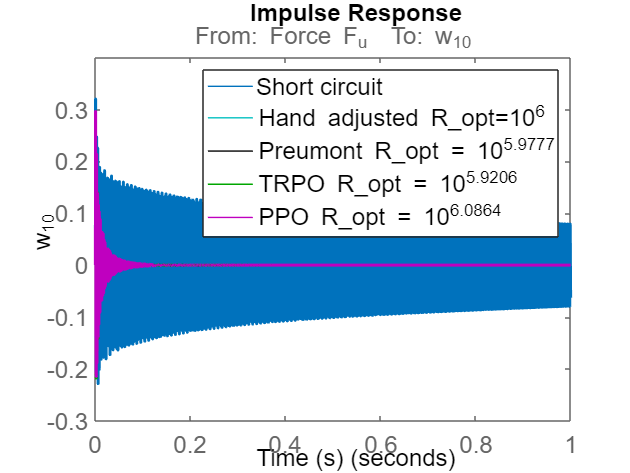

hold on
impulse(Sys_rs(end-1,2),time(end))
for i=1:length(R_shunt)
    Controle=s*R_shunt(i);
    Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
    impulse(Sys_rs_contr_R(end-1,2),time(end),color(i+2))
end

legend('Short circuit', ...
       'Hand adjusted R_{opt}=10^{'+string(log10(R_value))+'}', ...
       'Preumont R_{opt} = 10^{'+string(log10(R_opt_Preumont))+'}', ...
       'TRPO R_{opt} = 10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt} = 10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','northeast')
xlabel('Time (s)')
ylabel('w_{10}')

fontsize(fig7, 16, "points")
fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    savefig('Impulse_Sys_1D_R_opt_DRL')
    save_fig_pdf('Impulse_Sys_1D_R_opt_DRL')
end

### Reward variation 

color=['r'; 'c'; 'k'; 'g'; 'm'];
marker=['o'; 'x'; 'p'; '+'; 's'; 'd'];

R_shunt=10.^[0:0.5:12];
warning('off','all')

for i=1:length(R_shunt)
    reset(env);
    [nextObs,reward(i),isdone] = step(env,log10(R_shunt(i)));
end

Action = 0

distReward = 0.5953

Action = 0.5000

distReward = 0.5961

Action = 1

distReward = 0.5987

Action = 1.5000

distReward = 0.6069

Action = 2

distReward = 0.6319

Action = 2.5000

distReward = 0.7074

Action = 3

distReward = 0.9273

Action = 3.5000

distReward = 1.4948

Action = 4

distReward = 2.6146

Action = 4.5000

distReward = 4.2872

Action = 5

distReward = 5.8572

Action = 5.5000

distReward = 6.5914

Action = 6

distReward = 6.6963

Action = 6.5000

distReward = 6.3873

Action = 7

distReward = 5.6480

Action = 7.5000

distReward = 4.4977

Action = 8

distReward = 3.5653

Action = 8.5000

distReward = 2.9466

Action = 9

distReward = 2.6838

Action = 9.5000

distReward = 2.6912

Action = 10

distReward = 2.7321

Action = 10.5000

distReward = 2.7511

Action = 11

distReward = 2.7578

Action = 11.5000

distReward = 2.7600

Action = 12

distReward = 2.7607


fig8=figure

fig8 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 438 560 420]
       Units: 'pixels'

  Show all properties


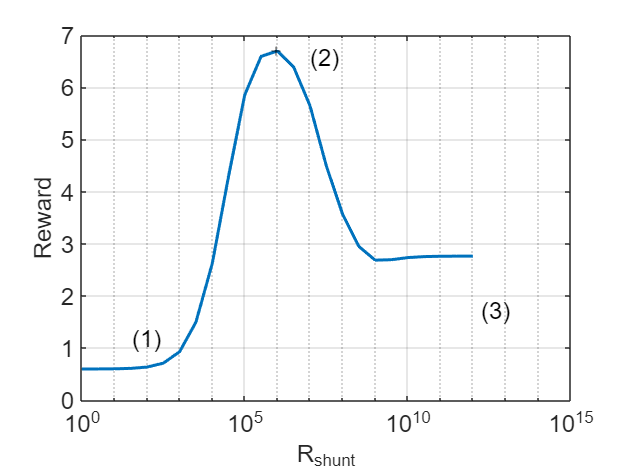

semilogx(R_shunt,reward(1:length(R_shunt)))
hold on
scatter(R_opt_Preumont,stop_training_value,marker(4),color(4))
xlabel('R_{shunt}')
ylabel('Reward')
grid('on')

annotation('textbox',...
    [0.479928571428571 0.849047619047621 0.0447142857142857 0.0723809523809524],...
    'String',{'(2)'},...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation('textbox',...
    [0.197785714285714 0.253809523809527 0.0447142857142858 0.0723809523809527],...
    'String','(1)',...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation('textbox',...
    [0.75135714285714 0.313809523809529 0.0447142857142857 0.0723809523809529],...
    'String','(3)',...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');

fontsize(fig8, 16, "points")
fig3.Position = [100 100 540*2 400*2];
% Get the line handles
hline = findall(gcf, 'type', 'line');
% Set the linewidth
set(hline, 'LineWidth', 2); % Change 2 to your desired linewidth


if save_figure_var == 1
    savefig('Reward_Sys_1D_R_opt_DRL')
    save_fig_pdf('Reward_Sys_1D_R_opt_DRL')
end

## Bibliography

[1] Preumont, A, "Vibration Control of Active Structures : An Introduction", 1999-04, *Meccanica* , Vol. 34, No. 2, Springer International Publishing, DOI:[10.1023/A:1004398914135](http://dx.doi.org/10.1023/A:1004398914135)